**IMU Simulation **

**Author: Michael Noyce**

Description

This program simulates the Invensense MPU6050 using the MATLAB imuSensor object. The input to the program is a sine wave based on the data collected from the MIZ by the SWIFT buoy (found here: xxx)

Current Program: Uses an ideal sine wave

Future program updates: use realistic wave input 

**Part 1: Accelerometer Simulation**

%Start of the Program: Accelerometer Simulation 

%Initially set the accelerometer with ideal parameters
params = accelparams

params =   accelparams with properties:

    MeasurementRange: Inf        m/s²      
          Resolution: 0          (m/s²)/LSB
        ConstantBias: [0 0 0]    m/s²      
    AxesMisalignment: [0 0 0]    %         

       NoiseDensity: [0 0 0]    (m/s²)/√Hz
    BiasInstability: [0 0 0]    m/s²      
         RandomWalk: [0 0 0]    (m/s²)*√Hz

           TemperatureBias: [0 0 0]    (m/s²)/°C
    TemperatureScaleFactor: [0 0 0]    %/°C     



%Create ideal sinusiod
N = 1000;
Fs = 100;
Fc = 0.25;

t = (0:(1/Fs):((N-1)/Fs)).';
acc = zeros(N, 3);
angvel = zeros(N, 3);
acc(:,1) = 1*sin(2*pi*Fc*t);

%Create imuSensor object
imu = imuSensor('SampleRate', Fs, 'ReferenceFrame', "NED", 'Accelerometer', params);

%IMU Accelerometer Characteristics
imu.Accelerometer.MeasurementRange = 39.24; % (m/s^2)
imu.Accelerometer.Resolution = 0.0011975; % ((m/s²)/LSB)
imu.Accelerometer.ConstantBias = [0, 0, 0]; % (m/s²)
imu.Accelerometer.AxesMisalignment = [0, 0, 0] % (%)

imu =   imuSensor with properties:

          IMUType: 'accel-gyro'
       SampleRate: 100
      Temperature: 25
    Accelerometer: [1×1 accelparams]
        Gyroscope: [1×1 gyroparams]
     RandomStream: 'Global stream'


imu.Accelerometer.NoiseDensity = [0.003924, 0.003924, 0.003924]; %((m/s²)/√Hz)
imu.Accelerometer.BiasInstability = [0.4905, 0.4905, 0.4905]% (m/s²)

imu =   imuSensor with properties:

          IMUType: 'accel-gyro'
       SampleRate: 100
      Temperature: 25
    Accelerometer: [1×1 accelparams]
        Gyroscope: [1×1 gyroparams]
     RandomStream: 'Global stream'


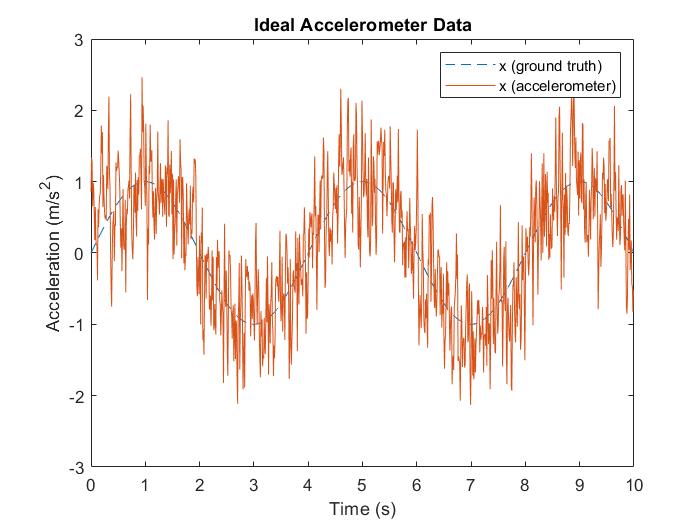

imu.Accelerometer.RandomWalk = [0, 0, 0]; %((m/s²)*√Hz)%imu.Accelerometer.TemperatureBias = [0, 0, 0]; %((m/s²)/°C)
%imu.Accelerometer.TemperatureScaleFactor = [0.02, 0.02, 0.02 ] %(%/°C)

%Determine Accelerometer Data output
[accData, ~] = imu(acc, angvel);
%Invert output as NED coordinate system assumes negative accelaration
%values 
accData = -1*accData;

%Plot output compared to ground truth
figure
plot(t, acc(:,1), '--', t, accData(:,1))
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')
title('Ideal Accelerometer Data')
legend('x (ground truth)', 'x (accelerometer)') 

**Part 2: Gyro Simulation**

%%Start of Program: Gyroscope Simulaiton  

%Initially set the Gyroscope with ideal parameters
params = gyroparams

params =   gyroparams with properties:

    MeasurementRange: Inf        rad/s      
          Resolution: 0          (rad/s)/LSB
        ConstantBias: [0 0 0]    rad/s      
    AxesMisalignment: [0 0 0]    %          

       NoiseDensity: [0 0 0]    (rad/s)/√Hz
    BiasInstability: [0 0 0]    rad/s      
         RandomWalk: [0 0 0]    (rad/s)*√Hz

           TemperatureBias: [0 0 0]    (rad/s)/°C    
    TemperatureScaleFactor: [0 0 0]    %/°C          
          AccelerationBias: [0 0 0]    (rad/s)/(m/s²)


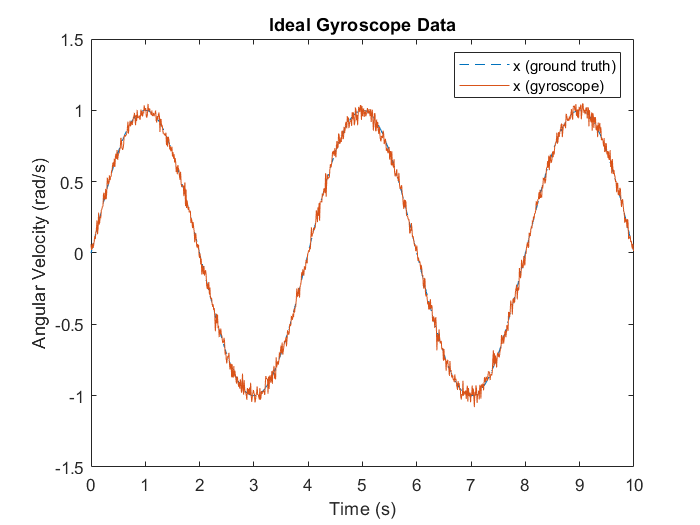


% Generate N samples at a sampling rate of Fs with a sinusoidal frequency
% of Fc.
N = 1000;
Fs = 100;
Fc = 0.25;

t = (0:(1/Fs):((N-1)/Fs)).';
acc = zeros(N, 3);
angvel = zeros(N, 3);
angvel(:,1) = sin(2*pi*Fc*t);

%Create imuSensor object
imu = imuSensor('SampleRate', Fs, 'Gyroscope', params);


%% IMU Charactersitics
imu.Gyroscope.MeasurementRange = 250.0; % rad/s
imu.Gyroscope.Resolution = 0.00013323; % (rad/s)/LSB
imu.Gyroscope.AxesMisalignment = [0, 0, 0]; % percent
imu.Gyroscope.ConstantBias = [0, 0, 0]; % rad/s
imu.Gyroscope.NoiseDensity = [0.005, 0.005, 0.005]; % (rad/s)/sqrt(Hz)
imu.Gyroscope.BiasInstability = [0, 0, 0]; % rad/s
imu.Gyroscope.RandomWalk = [0, 0, 0]; % (rad/s)*sqrt(Hz)
imu.Gyroscope.TemperatureBias = [0.34907, 0.34907, 0.34907]; % (rad/s)/(degrees C)
%imu.Gyroscope.TemperatureScaleFactor = 3.2; % %/(degrees C)
imu.Gyroscope.AccelerationBias = [0, 0, 0]; % (rad/s)/(m/s^2)

%Seperate


[~, gyroData] = imu(acc, angvel);

figure
plot(t, angvel(:,1), '--', t, gyroData(:,1))
xlabel('Time (s)')
ylabel('Angular Velocity (rad/s)')
title('Ideal Gyroscope Data')
legend('x (ground truth)', 'x (gyroscope)') 

**Part 3: Magnetometer Simulation **

%%Start of Program: Gyroscope Simulaiton  

%Initially set the Gyroscope with ideal parameters
params = magparams;

% Generate N samples at a sampling rate of Fs with a sinusoidal frequency
% of Fc.
N = 1000;
Fs = 100;
Fc = 0.25;

t = (0:(1/Fs):((N-1)/Fs)).';
acc = zeros(N, 3);
angvel = zeros(N, 3);
angvel(:,1) = sin(2*pi*Fc*t);
